# Sounding Data

clearvars;

## Input data files


data = 'E:\MATLAB Drive\Eclipse\Zac Acer\6.12.2020\';
datainput = 'digitalsonde2020061218Z_H2514394_ptu.csv';
gpsinput = 'groundtrack2020061218Z_H2514394.txt';
gpsdata = append(data,gpsinput);
atmdata = append(data,datainput);
Sounding_data = RS92_import(atmdata);
GPS_data = RS92_GPS_import(gpsdata);


## Sync data


sFrame = table2array(Sounding_data(:,1));
gFrame = table2array(GPS_data(:,1));
Sounding.Pressure = table2array(Sounding_data(:,2));
GPS.Alt = table2array(GPS_data(:,4));

if gFrame(1)<sFrame(1)
    i = find(gFrame==sFrame(1),1);
    GPS_data = circshift(GPS_data,length(gFrame)-i+1,1);
else
    i = find(sFrame==gFrame(1),1);
    Sounding_data = circshift(Sounding_data,length(sFrame)-i+1,1);
end

if length(gFrame)>length(sFrame)
    GPS_data = GPS_data(1:length(sFrame),:);
else
    Sounding_data = Sounding_data(1:length(gFrame),:);
end


## Create Data structure for data processing


Sounding.Pressure = table2array(Sounding_data(:,2));
Sounding.Temp = table2array(Sounding_data(:,3));
Sounding.Humidity = table2array(Sounding_data(:,4));
GPS.Alt = table2array(GPS_data(:,4));
GPS.Time = table2array(GPS_data(:,6));


## minor noise removel


% remove bad gps altutude data
for i = 1:length(GPS.Alt);
    if GPS.Alt(i) <= 0;
        GPS.Alt(i) = NaN;
    else
        GPS.Alt(i) = GPS.Alt(i);
    end
end


## Plot

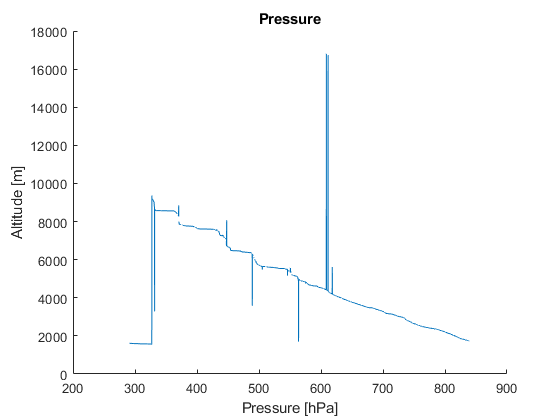


figure(2)
clf;
hold on;
plot(Sounding.Pressure,GPS.Alt)
title('Pressure');
xlabel('Pressure [hPa]');
ylabel('Altitude [m]');

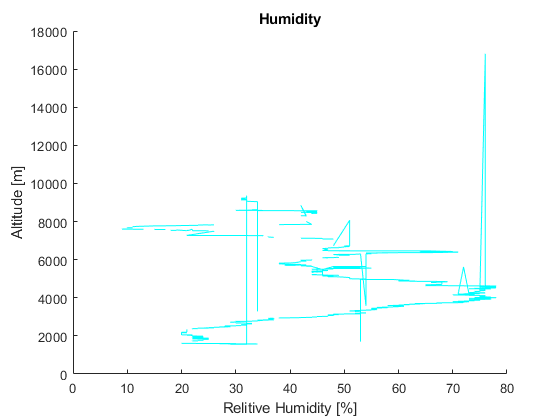


figure (3)
clf;
hold on;
plot(Sounding.Humidity,GPS.Alt,'c')
title('Humidity');
xlabel('Relitive Humidity [%]');
ylabel('Altitude [m]');

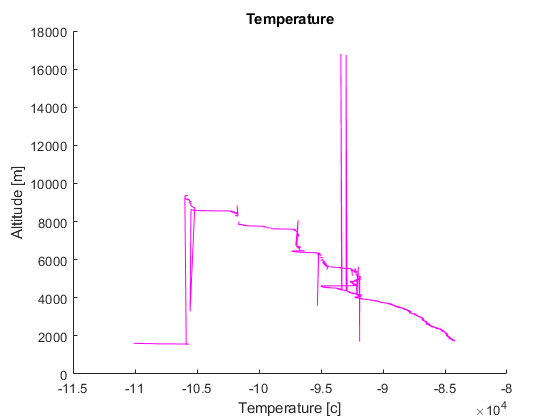


figure (3)
clf;
hold on;
plot(Sounding.Temp,GPS.Alt,'m')
title('Temperature');
xlabel('Temperature [c]');
ylabel('Altitude [m]');

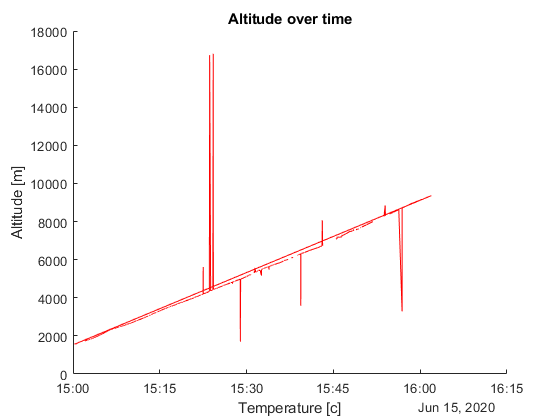


figure (4)
clf;
hold on;
plot(GPS.Time,GPS.Alt,'r')
title('Altitude over time');
xlabel('Temperature [c]');
ylabel('Altitude [m]');